% ใช้โมเดลจาก RBF01

% เคลียร์ข้อมูลก่อนรันโค้ดใหม่
clear all, close all, clc

% % เพิ่มเส้นทางของโฟลเดอร์ '0.Surrogate model & Optimization'
% % และโฟลเดอร์ย่อยทั้งหมดที่อยู่ภายในโฟลเดอร์นี้
% folder_path = '0.Surrogate model & Optimization';
% addpath(genpath(folder_path));

% โหลดข้อมูลจาก .m file
load("kmeans_sampling_training.mat")

% % กำหนดตัวแปรและแบ่งข้อมูลออกเป็นชุดฝึกและชุดทดสอบ
% โดยในโค้ดที่จะใช้ตัวแปรต้น X ร่วมกัน แต่แยกการสร้างโมเดลของ
% Electric Power และ HeatRejection

% กำหนดตัวแปร X 
X_train = X_sampling_training;
X_test;
% X_test = X_test;

% กำหนดตัวแปร Y1 % Electric Power 
Y1_ElectricalPower = clean_data(:,25);
Y1_ElectricalPower_train = Y1_sampling_training;
Y1_ElectricalPower_test = Y1_ElectricPower_test;

% กำหนดตัวแปร Y2 % Heat Rejection
Y2_HeatRejection = clean_data(:,26);
Y2_HeatRejection_train = Y2_sampling_training;
Y2_HeatRejection_test;

% Matrix transpose
X_train = X_train.';
X_test = X_test.';

% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'linear_spline', 'cubic_spline', 'thin_plate_spline',...
    'Gaussian', 'Multiquadraic', 'inverse_Quadric', 'inverse_Multiquadraic'}

% สร้าง structure สำหรับเก็บผลลัพธ์
results = struct();

% วนลูปเพื่อสร้างแบบจำลอง ทดสอบแบบจำลอง คำนวณค่า%RMSE 
% และบันทึกผลลัพธ์ไว้ใน structure ของแต่ละแบบจำลอง 
for i = 1:length(models)
    % สร้าง struct เพื่อเก็บตัวแปรของโมเดล
    model = struct();
    model.kernel = models{i};
    
    % Fit model โดยใช้ฟังก์ชัน rbf01 
    model.A = rbf01(X_train,model.kernel);
    
    % coefficient datermination
    model.ElectricalPower_coeff = inv(model.A)*Y1_ElectricalPower_train;
    model.HeatRejection_coeff = inv(model.A)*Y2_HeatRejection_train;
    
    % Predicted ใช้ฟังก์ชัน rbfpredictor
    model.ElectricalPower_Predicted = rbfpredictor(X_test,model.ElectricalPower_coeff,X_train,model.kernel);
    model.HeatRejection_Predicted = rbfpredictor(X_test,model.HeatRejection_coeff,X_train,model.kernel);
    
    % คำนวน %rmse
    model.ElectricalPower_PRMSE = ((sqrt(mean((Y1_ElectricalPower_test-model.ElectricalPower_Predicted').^2)))/(max(Y1_ElectricalPower)-min(Y1_ElectricalPower)))*100;
    model.HeatRejection_PRMSE = ((sqrt(mean((Y2_HeatRejection_test-model.HeatRejection_Predicted').^2)))/(max(Y2_HeatRejection)-min(Y2_HeatRejection)))*100;
    
    % เก็บผลลัพธ์ใน struct results
    results.(models{i}) = model;
end


% แสดงผลลัพธ์
fprintf('Heat Rejection PRMSE:\n');
for i = 1:length(models)
    fprintf('%s: %f\n', models{i}, results.(models{i}).HeatRejection_PRMSE);
end

fprintf('--------------------------------')
% แสดงผลลัพธ์
fprintf('Electrical Power PRMSE:\n');
for i = 1:length(models)
    fprintf('%s: %f\n', models{i}, results.(models{i}).ElectricalPower_PRMSE);
end


% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'linear_spline', 'cubic_spline', 'thin_plate_spline',...
    'Gaussian', 'Multiquadraic'};
names = {'Actual','RBF linear', 'RBF cubic', 'RBF thin plate spline',...
    'RBF Gaussian', 'RBF Multiquadraic'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
colors = {'r', '#77AC30', '#0072BD', '#4DBEEE', '#D95319', '#7E2F8E', '"A2142F'};
markers = {'*', '+', 'o', 'x', '^', 'd', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y1_ElectricalPower_test, Y1_ElectricalPower_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y1_ElectricalPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y1_ElectricalPower_test), max(Y1_ElectricalPower_test)]);

% ตกแต่งกราฟ
title(' Electric Power Actual vs RBF Predicted');

legend(names, 'Location', 'best');
hold off;

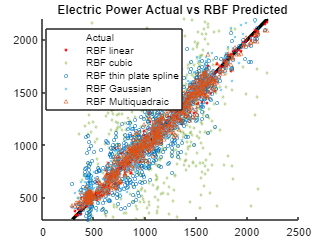


% สร้าง cell array เพื่อเก็บชื่อโมเดล
models = {'linear_spline', 'cubic_spline', 'thin_plate_spline',...
    'Gaussian', 'Multiquadraic'};
names = {'Actual','RBF linear', 'RBF cubic', 'RBF thin plate spline',...
    'RBF Gaussian', 'RBF Multiquadraic'};
% สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล

colors = {'r', '#77AC30', '#0072BD', '#4DBEEE', '#D95319', '#7E2F8E', '"A2142F'};
markers = {'*', '+', 'o', 'x', '^', 'd', '^'};

% พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
figure;
hold on;
% พล็อตค่าจริง
plot(Y2_HeatRejection_test, Y2_HeatRejection_test, 'k-',LineWidth = 3);
for i = 1:length(models)
    model = results.(models{i});
    plot(Y2_HeatRejection_test, model.HeatRejection_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
end
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);

% ตกแต่งกราฟ
title('Heat Rejection Actual vs RBF Predicted');

legend(names, 'Location', 'best');
hold off;

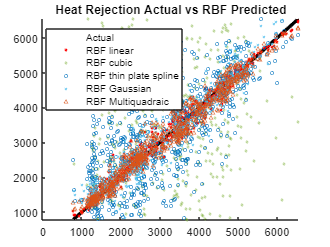

% % สร้าง cell array เพื่อเก็บชื่อโมเดล
% models = {'linear_spline'};
% names = {'Actual','RBF linear'};
% % สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
% colors = {'r'};
% markers = {'*'};
% 
% % พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง

% figure;
% hold on;
% % พล็อตค่าจริง
% plot(Y1_ElectricalPower_test, Y1_ElectricalPower_test, 'k-',LineWidth = 3);
% for i = 1:length(models)
%     model = results.(models{i});
%     plot(Y1_ElectricalPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
% end
% ylim([min(Y1_ElectricalPower_test), max(Y1_ElectricalPower_test)]);
% 
% % ตกแต่งกราฟ
% title(' Electric Power Actual vs RBF linear Predicted');
% 
% legend(names, 'Location', 'best');
% hold off;

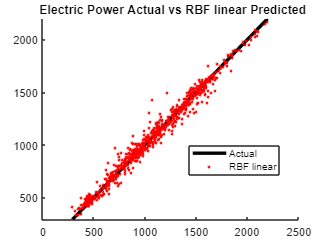

% % สร้าง cell array เพื่อเก็บชื่อโมเดล
% models = {'linear_spline', 'cubic_spline', 'thin_plate_spline',...
%     'Gaussian', 'Multiquadraic'};
% names = {'Actual','RBF linear', 'RBF cubic', 'RBF thin plate spline',...
%     'RBF Gaussian', 'RBF Multiquadraic'};
% % สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
% colors = {'r', '#77AC30', '#0072BD', '#4DBEEE', '#D95319', '#7E2F8E', '"A2142F'};
% markers = {'*', '+', 'o', 'x', '^', 'd', '^'};
% 

% % พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
% figure;
% hold on;
% % พล็อตค่าจริง
% plot(Y1_ElectricalPower_test, Y1_ElectricalPower_test, 'k-',LineWidth = 3);
% for i = 1:length(models)
%     model = results.(models{i});
%     plot(Y1_ElectricalPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
% end
% 
% 
% % ตกแต่งกราฟ
% title(' Electric Power Actual vs RBF Predicted');
% 
% legend(names, 'Location', 'best');
% hold off;

% 
% % สร้าง cell array เพื่อเก็บชื่อโมเดล
% models = {'inverse_Quadric', 'inverse_Multiquadraic'};
% names = {'Actual','inverse Quadric', 'inverse Multiquadraic'};
% % สร้างเซลล์เก็บสีและสัญลักษณ์ของแต่ละโมเดล
% colors = {'b', 'k'};
% markers = {'x', '^'};
% 
% % พล็อตค่าที่ทำนายโดยแต่ละโมเดลและเปรียบเทียบกับค่าจริง
% figure;
% hold on;
% % พล็อตค่าจริง
% plot(Y1_ElectricalPower_test, Y1_ElectricalPower_test, 'k-',LineWidth = 3);
% for i = 1:length(models)
%     model = results.(models{i});
%     plot(Y1_ElectricalPower_test, model.ElectricalPower_Predicted, markers{i}, 'Color', colors{i},'MarkerSize',3);
% end
% ylim([min(Y1_ElectricalPower_test), max(Y1_ElectricalPower_test)]);
% 
% % ตกแต่งกราฟ
% title(' Electric Power Actual vs Predicted');
% 
% legend(names, 'Location', 'best');
% hold off;

% % % % % % % % สร้างตารางข้อมูล % % % % % % % %
% claen_table = array2table(clean_data);
% 
% % กำหนดชื่อคอลัมน์
% claen_table.Properties.VariableNames = column_names;
% 
% % บันทึกตารางเป็นไฟล์ Excel
% writetable(claen_table, 'NEW_clean_data.xlsx');


% % สร้าง cell array เพื่อเก็บชื่อโมเดล
% models = {'linear_spline', 'cubic_spline', 'thin_plate_spline',...
%     'Gaussian', 'Mutiquadraic', 'inverse_Quadric', 'inverse_Multiquadraic'}
% 
% % สร้าง structure สำหรับเก็บผลลัพธ์
% results = struct();
% 
% % วนลูปเพื่อสร้างแบบจำลอง ทดสอบแบบจำลอง คำนวณค่า%RMSE 
% % และบันทึกผลลัพธ์ไว้ใน structure ของแต่ละแบบจำลอง 
% for i = 1:length(models)
% %     สร้าง struct เพื่อเก็บตัวแปรของโมเดล
%     model = struct();
%     model.kernel = models{i};
% %     Fit model โดยใช้ฟังก์ชัน rbf01 
%     model.A = rbf01(X_sampling_training,model.kernel);
%     
% %     coefficient datermination
%     model.ElectricalPower_coeff = inv(model.A)*Y1_ElectricalPower_train;
%     model.HeatRejection_coeff = inv(model.A)*Y2_HeatRejection_train;
% 
% %     Predicted ใช้ฟังก์ชัน rbfpredictor
%     model.ElectricalPower_Predicted = rbfpredictor(X_test,model.ElectricalPower_coeff,X_train,model.kernel);
%     model.HeatRejection_Predicted = rbfpredictor(X_test,model.HeatRejection_coeff,X_train,model.kernel);
% 
% %     คำนวน %rmse
%     model.ElectricalPower.prmse = ((sqrt(mean((Y1_ElectricalPower_test-model.EPwer.Predicted).^2)))/(max(Y1_ElectricalPower)-min(Y1_ElectricalPower)))*100;
%     model.HeatRejection.prmse = ((sqrt(mean((Y2_HeatRejection_test-model.HeatRejection_Predicted).^2)))/(max(Y2_HeatRejection)-min(Y2_HeatRejection)))*100;                    
% 
% %     เก็บผลลัพธ์ใน struct results
%     results.(models{i}) = model;
% end


% แสดงผลลัพธ์
for i = 1:length(models)
    fprintf('%s Model:\n', models{i})
    fprintf('Electric Power %RMSE: %f\n', results.(models{i}).ElectricalPower.prmse);
    fprintf('Heat Rejection %RMSE: %f\n\n', results.(models{i}).HeatRejection.prmse);
end


% พล็อตกราฟเปรียบเทียบค่าจริงและค่าทำนายของ Surrogate model แต่ละชนิด
figure
hold on
plot(Y1_ElectricalPower_test,Y1_ElectricalPower_test, 'k-', 'LineWidth', 1); % กราฟเส้นทึบแทนฟังก์ชันจริง
plot(Y1_ElectricalPower_test,linear.ElectricalPower_Predicted, 'bo', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย linear spline
plot(Y1_ElectricalPower_test,cubic.ElectricalPower_Predicted, 'rx', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย cubic spline
plot(Y1_ElectricalPower_test,thin.ElectricalPower_Predicted, 'gs', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย thin plate spline
plot(Y1_ElectricalPower_test,Gaussian.ElectricalPower_Predicted, 'md', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย Gaussian
plot(Y1_ElectricalPower_test,Multi.ElectricalPower_Predicted, 'y^', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย Multiquadraic
plot(Y1_ElectricalPower_test,inv_Quad.ElectricalPower_Predicted, 'cv', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย inverse Quadric
plot(Y1_ElectricalPower_test,inv_Multi.ElectricalPower_Predicted, 'kp', 'MarkerSize', 3); % กราฟจุดแทนค่าทำนาย inverse Multiquadraic
ylim([min(Y1_ElectricalPower), max(Y1_ElectricalPower)]); % ปรับแกน y เพื่อให้กราฟแสดงผลได้อย่างชัดเจน
legend('Real function', 'Linear spline', 'Cubic spline', 'Thin plate spline', 'Gaussian', 'Multiquadraic', 'Inverse Quadric', 'Inverse Multiquadraic', 'Location', 'NorthWest')
xlabel('Electric Power Actual value');
ylabel('Electric Power Predicted value');
title('Comparison of actual and Predicted values for Electric Power RBF surrogate models');
hold off;

figure
hold on
plot(Y2_HeatRejection_test,Y2_HeatRejection_test, 'k-', 'LineWidth', 1);  
plot(Y2_HeatRejection_test,linear.HeatRejection_Predicted, 'bo', 'MarkerSize', 3); 
plot(Y2_HeatRejection_test,cubic.HeatRejection_Predicted, 'rx', 'MarkerSize', 3); 
plot(Y2_HeatRejection_test,thin.HeatRejection_Predicted, 'gs', 'MarkerSize', 3);  
plot(Y2_HeatRejection_test,Gaussian.HeatRejection_Predicted, 'md', 'MarkerSize', 3); 
plot(Y2_HeatRejection_test,Multi.HeatRejection_Predicted, 'y^', 'MarkerSize', 3); 
plot(Y2_HeatRejection_test,inv_Quad.HeatRejection_Predicted, 'cv', 'MarkerSize', 3);
plot(Y2_HeatRejection_test,inv_Multi.HeatRejection_Predicted, 'kp', 'MarkerSize', 3);
ylim([min(Y2_HeatRejection_test), max(Y2_HeatRejection_test)]);
legend('Real function', 'Linear spline', 'Cubic spline', 'Thin plate spline', 'Gaussian', 'Multiquadraic', 'Inverse Quadric', 'Inverse Multiquadraic', 'Location', 'NorthWest')
xlabel('Cooling HeatRejection Actual value');
ylabel('Cooling HeatRejection Predicted value');
title('Comparison of actual and Predicted values for Cooling HeatRejection RBF surrogate models');
hold off;

idx = round(linspace(1, size(Y1_ElectricalPower_test, 1), 10));
figure
hold on
plot(idx, Y1_ElectricalPower_test(idx), 'k-', 'LineWidth', 2); % plot solid line representing the real function
plot(idx, linear.ElectricalPower_Predicted(idx)); % plot Predicted values using linear spline
plot(idx, cubic.ElectricalPower_Predicted(idx)); % plot Predicted values using cubic spline
plot(idx, thin.ElectricalPower_Predicted(idx)); % plot Predicted values using thin plate spline
plot(idx, Gaussian.ElectricalPower_Predicted(idx)); % plot Predicted values using Gaussian
 
plot(idx, Multi.ElectricalPower_Predicted(idx)); % plot Predicted values using Multiquadraic
% plot(idx, inv_Quad.ElectricalPower_Predicted(idx)); % plot Predicted values using inverse Quadric
% plot(idx, inv_Multi.ElectricalPower_Predicted(idx)); % plot Predicted values using inverse Multiquadraic

legend('Real function', 'Linear spline', 'Cubic spline', 'Thin plate spline',...
    'Gaussian', 'Multiquadraic', 'Location', 'northwest')
xlabel('index');
ylabel('Electric Power Predicted value');
title('Comparison of actual and Predicted Electric Power RBF models');
hold off;

idx = round(linspace(1, size(Y1_ElectricalPower_test, 1), 10));
figure
hold on
plot(idx, Y1_ElectricalPower_test(idx), 'k-', 'LineWidth', 2); % plot solid line representing the real function
plot(idx, inv_Quad.ElectricalPower_Predicted(idx)); % plot Predicted values using inverse Quadric
plot(idx, inv_Multi.ElectricalPower_Predicted(idx)); % plot Predicted values using inverse Multiquadraic

legend('Real function', 'Inverse Quadric', 'Inverse Multiquadraic','Location', 'southeast')
xlabel('index');
ylabel('Electric Power Predicted value');
title('Comparison of actual and Predicted Electric Power RBF models');
hold off;

idx = round(linspace(1, size(Y2_HeatRejection_test, 1), 10));
figure
hold on
plot(idx, Y2_HeatRejection_test(idx), 'k-', 'LineWidth', 2); % plot solid line representing the real function
plot(idx, linear.HeatRejection_Predicted(idx)); % plot Predicted values using linear spline
plot(idx, cubic.HeatRejection_Predicted(idx)); % plot Predicted values using cubic spline
plot(idx, thin.HeatRejection_Predicted(idx)); % plot Predicted values using thin plate spline
plot(idx, Gaussian.HeatRejection_Predicted(idx)); % plot Predicted values using Gaussian
plot(idx, Multi.HeatRejection_Predicted(idx)); % plot Predicted values using Multiquadraic
% plot(idx, inv_Quad.HeatRejection_Predicted(idx)); % plot Predicted values using inverse Quadric
% plot(idx, inv_Multi.HeatRejection_Predicted(idx)); % plot Predicted values using inverse Multiquadraic

legend('Real function', 'Linear spline', 'Cubic spline', 'Thin plate spline',...
    'Gaussian', 'Multiquadraic', 'Location', 'NorthWest')
xlabel('index');
ylabel('Cooling HeatRejection Predicted value');
title('Comparison of actual and Predicted Cooling HeatRejection RBF models');
hold off;

idx = round(linspace(1, size(Y2_HeatRejection_test, 1), 10));
figure
hold on
plot(idx, Y2_HeatRejection_test(idx), 'k-', 'LineWidth', 2); % plot solid line representing the real function
plot(idx, inv_Quad.HeatRejection_Predicted(idx)); % plot Predicted values using inverse Quadric
plot(idx, inv_Multi.HeatRejection_Predicted(idx)); % plot Predicted values using inverse Multiquadraic

legend('Real function','Inverse Quadric', 'Inverse Multiquadraic','Location', 'southeast')
xlabel('index');
ylabel('Cooling HeatRejection Predicted value');
title('Comparison of actual and Predicted Cooling HeatRejection RBF models');
hold off;

% % save ข้อมูล จาก Workspace 
% save('data_RBF01_model.mat');